## ***Problem Statement******: *****Consider a plane slab of large surface area and thickness 0.2m. Find temperature distribution and Rate of heat transfer at different location for given temperature and convection boundary conditions.**

## ***Assumptions******: *****1D, Steady state, variable thermal conductivity, non-zero heat generation.**

## ***Parameters*****: **

- **Temperature at far left surface of slab = 373K**

- **Convection condition at far right of the slab = Air at **$T_{\infty } =373K$** and **$h=45\;\left(\frac{W}{m^2 *K}\right)$

- $k=K_0 \left(1+\beta T\right)\;\left(\frac{W}{m*K}\right)$ where $\beta =9\ldotp 21*{10}^{-4\;} \;\left(\frac{1}{K}\right)$

- **L = 0.2m**

- 
$${\mathit{\mathbf{q}}}_{\mathrm{gen}} =30000\left(\frac{W}{m^3 }\right)$$


## ***Find*****: **

- **Temperature distribution **

- **Heat transfer flux at different locations **

- **Analytical solution     **

- **Numerical solution    **

- **Plot graph comparing analytical and numerical solution   **

- **determine how much nodes is sufficient for numerical method  **

- **No. of iterations of each selection of nodes  **

- **error graph per iteration **

- **Code time execution for each value of nodes    **

***1. Setting the parameters of the problem:***

clear
clc

format long  %Large no of float points are used to reduce the trucation error.
N = 3;  % No. of nodes - can be changed 

L = 0.2;  % Thickness of plane slab
delta_x = L/(N-1);   % Element size
x = 0:delta_x:L;
e = 0.000001;     % error thresold
beta = 0.000921; % for thermal conductivity 
k_0 = 14; 
q_gen = 30000;  % heat generation
h = 45;           % Heat transfer conefficent of air  
T_inf = 303;     % Air temperature

***2. Analytical Solution:***

***Governing Differential quation : ***$\frac{\mathrm{d}}{\textrm{d}x}k\left(T\right)\frac{\mathrm{d}}{\textrm{d}x}T+q_{\mathrm{gen}} =0$

Solving this we get: $T+\frac{\beta }{2}*T^2 =-q_{\mathrm{gen}} *\frac{x^2 }{2*k_o }+C_2 *x+C_3$

**Boundary conditions: **

- **At x=0, **$T_1 =373K$

- **At x=0.2 ,  **$-k\left(T\right)*\frac{\textrm{d}}{\textrm{d}x}T=h*\left(T-T_{\infty } \right)$

Solving above equation, final analytical solution becomes: $T\;\left(K\right)=\left(-2171\ldotp 5527+\sqrt{2171\ldotp {5527}^2 +4*\left(-2326663\ldotp 56*x^2 +450438\ldotp 65*x\right)+949118\ldotp 1325}\right)\frac{\;1}{2}\;$

**After solving for x=0.2 , T = 371.9K**

**Maximum Temperature will be T = 380.45K  at x = 0.097m **

**Heat flux (**$\frac{W}{m^2 }$**) = **$30000*x-2898\ldotp 598$

x_ana = linspace(0,0.2,100);
T_ana = (-2171.5527 + sqrt(2171.5527^2 + 4*(-2326663.56*(x_ana.^2) + 450438.65*x_ana + 949118.1325)))/2;
Q_flux_ana = 30000*x_ana - 2898.598;

***3. Numerical Solution:***

**After discritizing the differential equation, we get algebric equations,**

- **for node 1: **$T_{1\;} =373K$ (Temperature boundary condition )

- **for inner nodes (2 to N-1): **$T_n =\frac{\left(T_{n+1} +T_{n-1} +\frac{\beta }{2}*\left(T_{n+1}^2 +T_{n-1}^2 -2*T_n^2 \right)+\frac{\left(q_{\mathrm{gen}\;} *\Delta x^2 \right)}{K_o }\right)}{2}$

- **for last node (N): **$T_N =\frac{\left(T_{N-1} +\frac{\beta }{2}*\left(T_{N-1}^2 \;-T_N^2 \right)+\frac{\left(q_{\mathrm{gen}} *\Delta x^2 \right)}{2*K_o }+\frac{\left(h*\Delta x*T_{\infty } \right)}{K_o }\right)}{\left(1+\frac{\left(h*\Delta x\right)}{K_o }\right)}$

T_guess = zeros(1,N);  % Initial guess for gauss-seidel iteration 
T_guess(1) = 373;

T_current = T_guess;

% First iteration
tic;
i = 0;
Max_Error = 0;
[T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_current, N, delta_x, h, k_0, beta,q_gen, T_inf, i, Max_Error); 

% iterating until the solution converges (error goes below the thresold value)
while max(AbsoluteError) > e
    [T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_new,N,delta_x,h,k_0,beta,q_gen,T_inf,i,Max_Error);
end
TimeElapsed = toc

TimeElapsed =    0.036746800000000


Iterations = i

Iterations =     18



% Heat flux by numerical method
for n=1:N
    if n==1
        Q_flux_numerical(n)= -k_0*(1+beta*T_new(n))*((T_new(n+1)-T_new(n))/delta_x) + q_gen*delta_x/2;
    elseif n>=2 && n<= N-1
        Q_flux_numerical(n)= -k_0*(1+beta*T_new(n))*((T_new(n+1)-T_new(n-1))/(2*delta_x)) + q_gen*delta_x;
    else 
        Q_flux_numerical(n)= -k_0*(1+beta*T_new(n))*((T_new(n)-T_new(n-1))/delta_x) + q_gen*delta_x/2;
    end
end


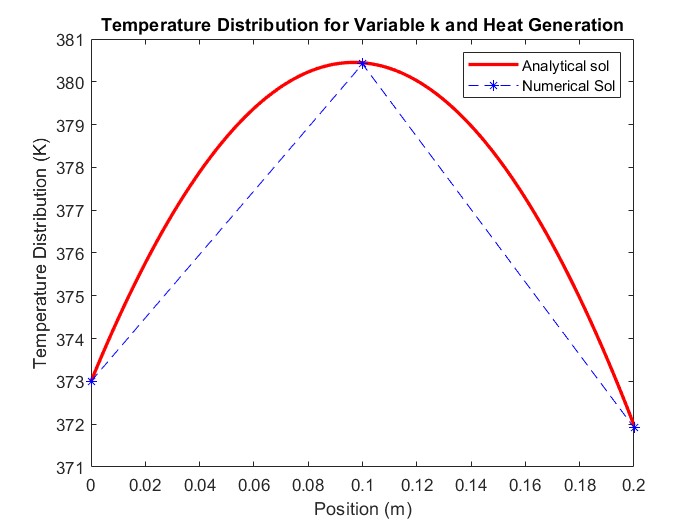

plot(x_ana, T_ana, "r", "LineWidth", 2)
hold on 
plot(x, T_new, "b--*")
xlabel("Position (m)")
ylabel("Temperature Distribution (K)")
legend("Analytical sol","Numerical Sol")
title("Temperature Distribution for Variable k and Heat Generation")
hold off

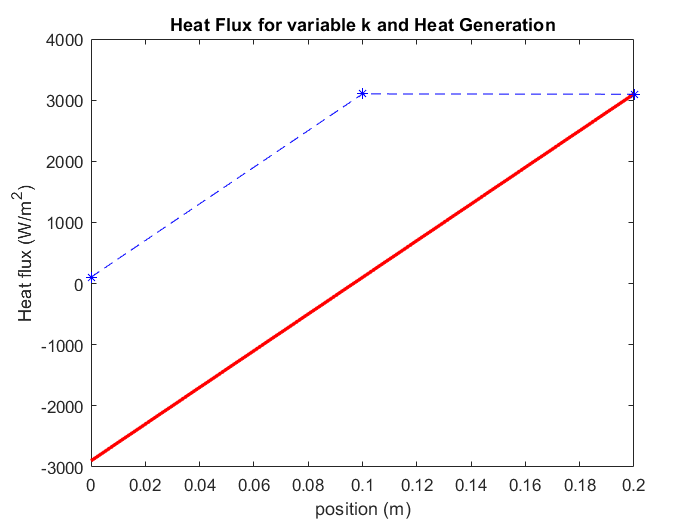


plot(x_ana, Q_flux_ana, "r", "LineWidth", 2)
hold on 
plot(x, Q_flux_numerical, "b--*")
xlabel("position (m)")
ylabel("Heat flux (W/m^2)")
title("Heat Flux for variable k and Heat Generation")
hold off

format short

***4. Numerical Iterator based on Gauss-Siedel method:***

function [T_new, AbsoluteError, Max_Error, i] = NumericalMethod(T_current, N, delta_x, h, k_0, beta,q_gen,T_inf, i, Max_Error)
    T_new(1) = 373; % far left node is at constant temperature 
    for n = 2:N
        if n < N % For inner nodes 
            % use of latest value for the calculation of next temperature at different position 
            T_new(n) = (T_current(n+1)+T_new(n-1) +(beta/2)*(T_current(n+1)^2 + T_new(n-1)^2 - 2*(T_current(n)^2))+(q_gen*(delta_x^2))/k_0)/2; 
            
        elseif n == N  % For Node at the far right surface influenced by convection
            T_new(n) = (T_new(n-1)+(beta/2)*(T_new(n-1)^2 - T_current(n)^2)+(q_gen*(delta_x^2))/(2*k_0)+(h*delta_x*T_inf)/k_0)/(1+(h*delta_x/k_0));
        end
        
    end
    
    i = i +1;
    AbsoluteError = abs(T_new - T_current); % absolute error at each node
    
end







